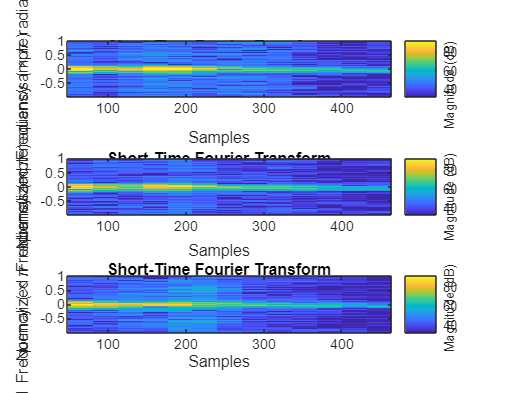

localDataPath = '/data/soil_gravel_concrete';
captureName = 'concrete.frames';
[concrete_frameTot, concrete_framesBB, ~] = proc_frames(localDataPath, captureName);

localDataPath = '/data/soil_gravel_concrete';
captureName = 'gravel.frames';
[gravel_frameTot, gravel_framesBB, ~] = proc_frames(localDataPath, captureName);

localDataPath = '/data/soil_gravel_concrete';
captureName = 'soil.frames';
[soil_frameTot, soil_framesBB, frameRate] = proc_frames(localDataPath, captureName);

figure
subplot(2,1,1)
plot(median(concrete_frameTot, 2))
hold on
plot(median(gravel_frameTot, 2))
plot(median(soil_frameTot, 2))
legend(["Concrete", "Gravel", "Soil"])
xlabel('Range Bins')
ylabel('DAC')
title('Raw radar frames')

subplot(2,1,2)
plot(median(abs(concrete_framesBB), 2))
hold on
plot(median(abs(gravel_framesBB), 2))
plot(median(abs(soil_framesBB), 2))
legend(["Concrete", "Gravel", "Soil"])
xlabel('Range Bins')
ylabel('DAC')
title('Radar frames after digital downcovert')


[concrete_captureFT, ~] = proc_fft(concrete_framesBB, frameRate, 100);
[gravel_captureFT, ~] = proc_fft(gravel_framesBB, frameRate, 100);
[soil_captureFT, ~] = proc_fft(soil_framesBB, frameRate, 100);

% figure
% subplot(3,1,1)
% [s, f, t] = stft(median(concrete_framesBB, 2));
% % mesh(t, f, abs(s).^2);
% subplot(3,1,2)
% s = stft(median(gravel_framesBB, 2));
% % imagesc(abs(s))
% subplot(3,1,3)
% s = stft(median(soil_framesBB, 2));
% % imagesc(abs(s))